# Example 7.1

Determine the flexural and Young’s moduli of E-glass/epoxy laminated beams having stacking sequences of [0/90/0]s and [90/0/90]s. The ply moduli are $E_1$ = 5 × 10^6 psi (34.48 GPa) and $E_2$= 1.5 × 10^6 psi (10.34 GPa), and the plies all have the same thickness.

`Solution:`** flexural modulus** for the [0/90/0]s laminated beam:

..................eq. 7.9 

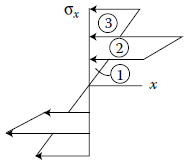

clc
clear all

E1= 5e6

E1 = 5000000

E2= 1.5e6   %psi

E2 = 1500000

theta = [0 90 0 0 90 0]     % stacking sequence

theta =      0    90     0     0    90     0


N= 6   % total number of plies

N = 6

n_0 = 4   % no. of 0 degree ply

n_0 = 4

n_90 = 2    % n. of 90 degree ply

n_90 = 2


E_ply = [E1 E2 E1]   %psi, ply modulii of [0/90/0]s

E_ply =      5000000     1500000     5000000



E_f = 0 ;  % initialization
for j= 1:N/2
    E_ff = (8/N^3)*E_ply(j)*(3*j^2 -3*j +1);
    E_f= E_f +E_ff   ;            
end
E_f    %in psi

E_f = 4.0926e+06

The **Young’s modulus, or extensional modulus**, can be estimated by using the rule of mixtures  , where $v_1$ = volume fraction of longitudinal (0°) plies and $v_2$ = volume fraction of transverse (90°) plies

v1= n_0/N 

v1 = 0.6667

v2= n_90/N

v2 = 0.3333

E_x = E1*v1 + E2*v2   %in psi

E_x = 3.8333e+06

**(b)** For the [90/0/90]s, beam 

E1= 5e6  % for 0 degree ply

E1 = 5000000

E2= 1.5e6   %psi, for 90 degree ply

E2 = 1500000

theta = [90 0 90 90 0 90]     % stacking sequence

theta =     90     0    90    90     0    90


N= 6   % total number of plies

N = 6

n_0 = 2   % no. of 0 degree ply

n_0 = 2

n_90 = 4  % n. of 90 degree ply

n_90 = 4


E_ply = [E2 E1 E2]   %psi, ply modulii of [0/90/0]s

E_ply =      1500000     5000000     1500000


E_f = 0 ;  % initialization
for j= 1:N/2
    E_ff = (8/N^3)*E_ply(j)*(3*j^2 -3*j +1);
    E_f= E_f +E_ff   ;            
end
E_f    %in psi

E_f = 2.4074e+06

The **Young’s modulus, or extensional modulus**, can be estimated by using the rule of mixtures  , where $v_1$ = volume fraction of longitudinal (0°) plies and $v_2$ = volume fraction of transverse (90°) plies

v1= n_0/N 

v1 = 0.3333

v2= n_90/N

v2 = 0.6667

E_x = E1*v1 + E2*v2   %in psi

E_x = 2.6667e+06